## FSTD_VALIDATION

This script will validate the FSTD construction through CICE history

fields to make sure everything is behaving as expected.

Aim: To get from afsdn to aice

Method:

1. Integrate aicen to aice

2. Integreate 

% Preamble
clear all
close all
addpath functions
addpath packages/bedmap2_toolbox_v4
filename = 'cases/fixedwaves/history/iceh.2005-01-01.nc';
% Read the header
ncdisp(filename)

Source:
           /Users/noahday/GitHub/CICE-plotting-tools/cases/fixedwaves/history/iceh.2005-01-01.nc
Format:
           classic
Global Attributes:
           title       = 'sea ice model output for CICE'
           contents    = 'Diagnostic and Prognostic Variables'
           source      = 'Los Alamos Sea Ice Model, CICE_6.2.0'
           comment     = 'This year has 365 days'
           comment2    = 'File written on model date 20050102'
           comment3    = 'seconds elapsed into model date:      0'
           conventions = 'CF-1.0'
           history     = 'This dataset was created on 2022-02-08 at 20:17:42.6'
           io_flavor   = 'io_netcdf'
Dimensions:
           d2        = 2
           ni        = 320
           nj        = 384
           nc        = 5
           nkice     = 7
           nksnow    = 1
           nkbio     = 3
           nkaer     = 5
           time      = 1     (UNLIMITED)
           nvertices = 4
           nf        = 16
Variables:
    time       

% 
grid = 'gx1';
ssd = 0;
sector = "EA";
user = 'noahday'; %a1724548, noahday, Noah
case_name = 'fixedwaves';
if ssd == 1
    ssd_dir = '/Volumes/Noah_SSD/run_data';
    filedir = strcat(ssd_dir,case_name);
else
    filedir = strcat('cases/',case_name);
end

day = 1;
month_init = 1;
year = 2005;
date = sprintf('%d-0%d-0%d', year, month_init, day);
months = [1];
dim = 2;
[lat,lon,row] = grid_read(grid);

figcount = 0;

date = sprintf('%d-0%d-0%d', year, month_init, day);
filename = strcat(filedir,"/history/iceh.",date,".nc");
[len, wid] = size(lat);

Aim 1: Verify $\sum_{n=0}^{N_C} \sum_{k=0}^{N_f} a_{in} F_{in,k} = 1$

dim = 4;
variable = "afsdn";
NFSD = ncread(filename,"NFSD");
NCAT = ncread(filename,"NCAT");
afsdn_data = data_format_sector(filename,variable,sector,dim);
[len, wid, dep, thick] = size(afsdn_data);
double_sum = zeros(len,wid);
for i = 1:len
    for j = 1:wid
        double_sum = sum(afsdn_data,[3,4]);
    end
end
double_int = zeros(len,wid);
fsd_int = zeros(len,wid);
for i = 1:len
    for j = 1:wid
        for n = 1:thick
            temp(1:16) = afsdn_data(i,j,:,n);
            fsd_int(i,j,n) = temp*NFSD;
        end
        temp2(1:5) = fsd_int(i,j,:);
        double_int(i,j) = temp2*NCAT;
    end
end


%% Plotting
figcount = figcount + 1;
figure(figcount)
t = tiledlayout(1,3)

t =   TiledChartLayout with properties:

    TileArrangement: 'fixed'
           GridSize: [1 3]
            Padding: 'loose'
        TileSpacing: 'loose'

  Show all properties


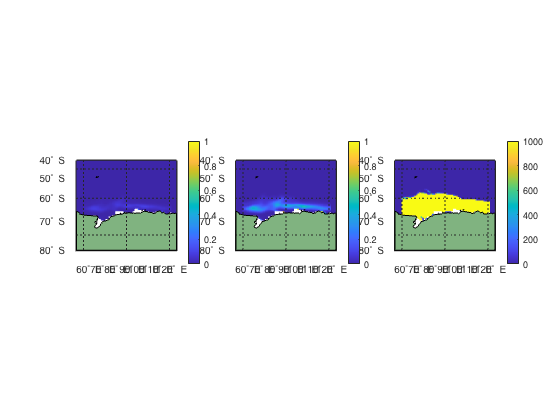

nexttile
map_plot(double_sum,variable,sector,grid,[0,1]);
% Compare with aice
variable = "aice";
aice_data = data_format_sector(filename,variable,sector,dim);
nexttile
map_plot(aice_data,variable,sector,grid,[0,1]);
nexttile
map_plot(double_int,variable,sector,grid,[0,10000]);

dim = 3;
variable = "afsd";
NFSD = ncread(filename,"NFSD");
fsd_data = data_format_sector(filename,variable,sector,dim);
%     idx = fsd_data > 10; 
%     fsd_miz = fsd_data;
%     fsd_miz(idx) = 0.0;
for i = 1:len
    for j = 1:wid
        fsd_pdf = zeros(1,length(NFSD));
        for k = 1:length(NFSD)
            fsd_pdf(k) = fsd_data(i,j,k);
        end
        fsd_miz(i,j) = fsd_pdf*(NFSD.^2*pi); % Fraction x Area
        %if ~isnan(fsd_pdf*(NFSD.^2*pi))
        %    temp = fsd_pdf.*(NFSD.^2*pi);
        %end
    end
end
figcount = figcount + 1;
figure(figcount)
map_plot(fsd_miz,variable,sector,grid,[0,1000]);

% Normalize FSD per cell
variable = "afsd";
NFSD = ncread(filename,"NFSD");
NCAT = ncread(filename,"NCAT");
dim = 3;
fstd_data = data_format_sector(filename,variable,sector,dim); % (x,y,fsd,itd)
for i = 1:len
    for j = 1:wid
        fsd_pdf = zeros(1,length(NFSD));
        for k = 1:length(NFSD)
%                 % Normalize ITD
%                 for l = 1:length(NCAT)
%                     itd_pdf(l) = fstd_data(i,j,k,l)/sum(fstd_data(i,j,k,:));
%                 end
%                 % Integrate the ITD
%                 Int_itd = itd_pdf*NCAT;
%                 fsd_data = fstd_data(:,:,:,1);
            % Intergrate w.r.t. FSD
            fsd_pdf(k) = fsd_data(i,j,k)/sum(fsd_data(i,j,:));
        end
        fsd_miz(i,j) = fsd_pdf*NFSD; % Weighted Average
    end
end
figcount = figcount + 1;
figure(figcount)
map_plot(fsd_miz,variable,sector,grid,[0,1000]);


% FSDrad 
variable = "fsdrad";
fsdrad_data = data_format_sector(filename,variable,sector,2);
figcount = figcount + 1;
figure(figcount)
map_plot(fsdrad_data,variable,sector,grid,[0,1000]);

% AICE 
variable = "aice";
aice_data = data_format_sector(filename,variable,sector,2);
figcount = figcount + 1;
figure(figcount)
map_plot(aice_data,variable,sector,grid,[0,1]);

figcount = figcount + 1;
figure(figcount)
map_plot(fsdrad_data-fsd_miz,variable,sector,grid,[0,1000]);
